## Problem 1

## Question (a)

We consider the BVP:


$$$$
-\frac{\mathrm{d}}{\mathrm{d} x}\left( \left(1 + x^2\right)\frac{\mathrm{d} u}{\mathrm{d} x}\right) = 2, \qquad 0 < x < 1,\quad u(0) = 0,\quad u'(1) = -3.
$$$$


and "solve" it using the FEM with just *one linear element* on $[0,1]$ with two nodes placed at $x = 0$ and $x = 1$.

clearvars
close all
syms x;
nodes = [0; 1];
h = nodes(2) - nodes(1);
a(x) = 1+x^2;
f = 2;
U0 = 0;
DU1 = -3;

Psi(x) = [nodes(2)-x, x-nodes(1)] / h;

K = int(1+x.^2,x,nodes(1),nodes(2)) * [1, -1; -1, 1] / h^2

$$K = \left(\begin{array}{cc} \frac{4}{3} & -\frac{4}{3}\\ -\frac{4}{3} & \frac{4}{3} \end{array}\right)$$

**Solution:** $K_{1,1} = \frac{4}{3} = K(1,1) = 1.33333$.

fprintf("K(1,1) = %.5f\n", K(1,1))

K(1,1) = 1.33333


## Question (b)

F = int(f * Psi(x)',x,nodes(1),nodes(2))

$$F = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

**Solution: **$F_{1} = 1$.

fprintf("F(1) = %.5f", F(1))

F(1) = 1.00000

## Question (c)

Solving the system for the primary variables. **Note: **recall the $F$ was already computed in item (b)! so we need to allocate memory for vectors $u$ and $Q$. 

Q = zeros(2,1);
u = zeros(2,1);

fixedNods = 1;
freeNods = 2;

%Boundary Conditions (B.C.):
% Natural
Q(2) = a(nodes(2))*DU1;
% Essential
u(1) = 0;

%Reduced system
Fm = Q(freeNods) + F(freeNods) - K(freeNods,fixedNods)*u(fixedNods)

$$Fm = -5$$

Km = K(freeNods,freeNods);
um = Km \ Fm;
u(freeNods) = um;
fprintf("u(1) = %.5f\nu(2) = %.5f\n", u(1), u(2));

u(1) = 0.00000
u(2) = -3.75000


Compute the average:

uBar = (u(1) + u(2)) / 2;
fprintf("Averaged U = %.5f", uBar)

Averaged U = -1.87500

**Solution:** $\bar{U} = -1.87500$.

## Question (d)

Exact solution $u(x) = -4\arctan(x) - \ln\left(1+x^2\right)$. We look for the absolute maximum of $\left|u(x) - u_{h}(x)$| at the closed interval $I = [0,1]$.

err(x) = - 4 * atan(x) - log(1+x.^2) - Psi(x) * u;
pretty(err(x))

$$\frac{15\,x}{4}-\log\left(x^{2}+1\right)-4\,\mathrm{atan}\left(x\right)$$

derr = diff(err(x),x)

$$derr = \frac{15}{4}-\frac{4}{x^{2}+1}-\frac{2\,x}{x^{2}+1}$$


eqn = simplify(derr * 4*(x^2 + 1));
pretty(eqn)

$$15\,x^{2}-8\,x-1$$

sols = solve(eqn,x);
pretty(sols)

$$\left(\begin{array}{c} \frac{4}{15}-\frac{\sqrt{31}}{15}\\ \frac{\sqrt{31}}{15}+\frac{4}{15} \end{array}\right)$$

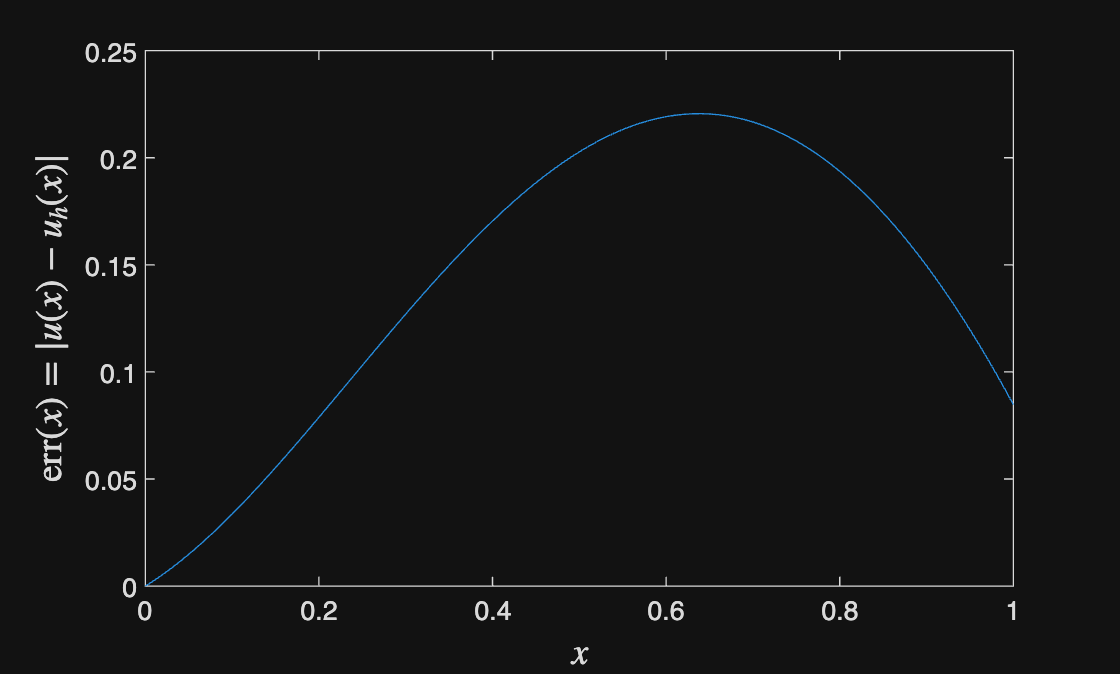

t = nodes(1):0.01:nodes(2);
errValues = double(err(t));
plot(t,abs(errValues),'-')
xlabel('$x$',Interpreter='LaTeX',FontSize=14)
ylabel('$\mathrm{err}(x) = |u(x)-u_{h}(x)|$',Interpreter='LaTeX', FontSize=14)

fprintf("Valor màxim del error a l'interval [%d,%d], s'assoleix al punt x %c %.5f", ...
    nodes(1),nodes(2), char(0x2248), double(sols(2)))

Valor màxim del error a l'interval [0,1], s'assoleix al punt x ≈ 0.63785

**Solution:** $\arg\max\limits_{0\le x \le 1} \left| u(x) - u_{h}(x)\right| = \frac{\sqrt{31}}{15} + \frac{4}{15} = 0.63785$.